# Problema 3 -Suplimentara

# 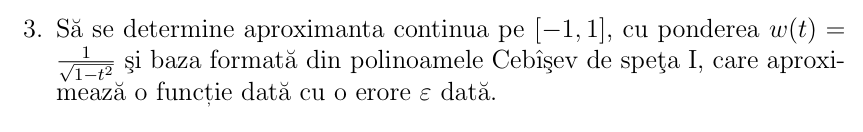

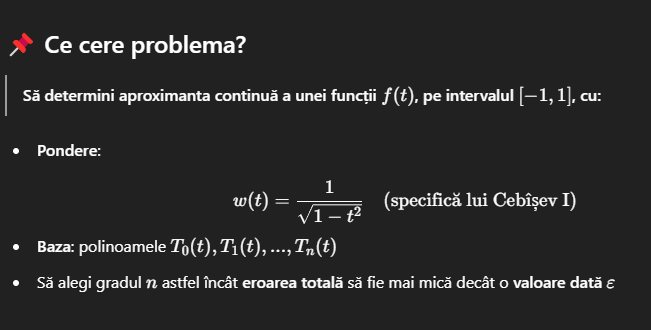

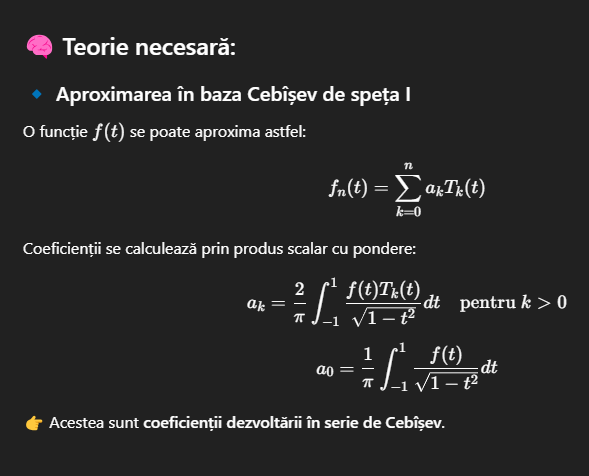

function [c, err_est, n_final] = aprox_continua_chebyshev(f_handle, epsilon, n_max)

    % Incepem cu grad mic si crestem pana eroarea e sub epsilon
    for n = 1:n_max
        % Noduri Gauss-Chebyshev
        k = 1:n;
        x_k = cos((2*k - 1) * pi / (2 * n));
        
        % Evaluam functia in aceste puncte
        f_vals = f_handle(x_k);

        % Calculam coeficientii Fourier-Chebyshev
        c = zeros(n, 1);
        for j = 1:n
            Tj_vals = cos((j - 1) * acos(x_k));  % T_{j-1}(x_k)
            if j == 1
                c(j) = sum(f_vals .* Tj_vals) * (1 / n);
            else
                c(j) = 2 * sum(f_vals .* Tj_vals) * (1 / n);
            end
        end

        % Estimam eroarea prin norma L2 patratica:
        % ε^2 ≈ ∑_{k > n} c_k^2 → putem aproxima cu ultimii termeni
        % Aici ne oprim dacă contributia ultimului coeficient e mica
        err_est = abs(c(end));
        if err_est < epsilon
            n_final = n;
            return;
        end
    end

    warning('Nu s-a putut obține precizia cerută în %d pași.', n_max);
    n_final = n_max;
end

f = @(x) exp(x);     % functia de aproximat
eps_dorit = 1e-3;    % precizia ceruta
n_max = 50;          % gradul maxim permis

[c, err_final, grad_final] = aprox_continua_chebyshev(f, eps_dorit, n_max);

fprintf('Grad final: %d\n', grad_final);

Grad final: 6


fprintf('Eroare estimata: %.5e\n', err_final);

Eroare estimata: 5.39728e-04


disp('Coeficientii Fourier-Chebyshev:');

Coeficientii Fourier-Chebyshev:


disp(c');

    1.2661    1.1303    0.2715    0.0443    0.0055    0.0005

